# Pendulum Simulation

## Simulating Dynamics without Control

### Paramters

clc;clear;close all;

% Gravity (m/s^2)
g = 9.81;
% length
l = 1;
% mass 
m = 1;
% spring constant
k=1;

% Simulation time span (s) 
T = 0.0001;
t_span = 0:T:5;

### Initial Conditions

x0 = 0.1;
x0_dot = 0;
theta0 = pi/2;
theta0_dot = 0;

% Initialize state vector
x0 = [ x0, x0_dot, theta0, theta0_dot]

x0 =     0.1000         0    1.5708         0


### Solving the ODEs

% Use ode45 to solve for x_dot for your defined time span 
[t_actual,x_actual] = ode45(@(t,x) pendODEs(t,x,m,l,k,g),t_span,x0);

### Plot the Results

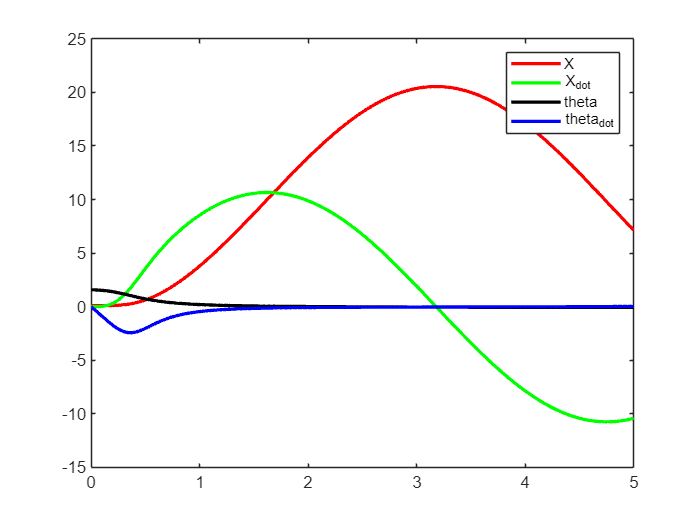

% Plot the results over the time span
plot(t_actual,x_actual(:,1),"red",t_actual,x_actual(:,2),"green",t_actual,x_actual(:,3),"black",t_actual,x_actual(:,4),"blue",LineWidth=2)
legend("X", "X_{dot}", "theta", "theta_{dot}");

## Simulating Dynamics with Control

### Setting up State Space Equations

% Using the same state vector defined in "pendODEs.m" (redefine it here), find the A,B, and C state space matricies.

syms pos pos_dot theta theta_dot

% State vector 
X = [pos;pos_dot;theta;theta_dot]

$$X = \left(\begin{array}{c} \mathrm{pos}\\ \dot{\mathrm{pos}}\\ \theta \\ \dot{\theta } \end{array}\right)$$


% Equilibrium Point
X0 = zeros(4,1);

% for ease
c_P = cos(theta);
s_P = sin(theta);

% State transition functition
f = [pos_dot;
    (l+pos)*theta_dot^2+g*c_P-k/m*pos;
    theta_dot;
    (-2*pos_dot*theta_dot-g*s_P)/(l+pos);
]

$$f = \left(\begin{array}{c} \dot{\mathrm{pos}}\\ \left(\mathrm{pos}+1\right)\,{\dot{\theta }}^{2}-\mathrm{pos}+\frac{981\,\cos\left(\theta \right)}{100}\\ \dot{\theta }\\ -\frac{\frac{981\,\sin\left(\theta \right)}{100}+2\,\dot{\mathrm{pos}}\,\dot{\theta }}{\mathrm{pos}+1} \end{array}\right)$$


% Finding A, B, C (to linearize, we need to use the jacobian)
A = jacobian(f,X)

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ {\dot{\theta }}^{2}-1 & 0 & -\sigma_{1} & 2\,\dot{\theta }\,\left(\mathrm{pos}+1\right)\\ 0 & 0 & 0 & 1\\ \frac{\sigma_{1}+2\,\dot{\mathrm{pos}}\,\dot{\theta }}{{\left(\mathrm{pos}+1\right)}^{2}} & -\frac{2\,\dot{\theta }}{\mathrm{pos}+1} & -\frac{981\,\cos\left(\theta \right)}{100\,\left(\mathrm{pos}+1\right)} & -\frac{2\,\dot{\mathrm{pos}}}{\mathrm{pos}+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,\sin\left(\theta \right)}{100} \end{array}$$

A_eq = subs(A,X,X0)

$$A\_eq = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{981}{100} & 0 \end{array}\right)$$

B_eq = [0; 0; 0; 0] %assuming no input

B_eq =      0
     0
     0
     0


C = [0 0 1 0]; %reading theta
D = [0];
